# Técnicas de procesamiento de señales y datos (MUIE)

## Ejercicio práctico bloque 4.2.1. Filtrado básico (v3.0)

### Objetivo

El objetivo de este ejercicio es la familizarización con la herramienta `filterDesigner` y la evaluación de distintas estrategias de filtrado digital.  Disculpad que a veces no aparezcan tildes, pero al cambiar de version de matlab, hay un bug que no permite escribirlas.

### Señales disponibles

#### Medida de las tensiones y corrientes de un convertidor DC/AC

Capturadas a una frecuencia de muestreo de 5KHz y proporcionadas por Santiago Cóbreces, que contienen 34 columnas, de las que sólo se indican las relevantes a continuación:

- La primera contiene el índice temporal medido en muestras

- Las columnas 2, 3 y 4 contienen las tres fases (I1A, I1B e I1C) de las corrientes I1 de salida del conversor

- Las columnas 5, 6 y 7 contienen las tres fases (I2A, I2B e I2C) de las corrientes I2 de red

- Las columnas 8, 9 y 10 conntienen las tres fases (EGA, EGB y EGC) de las tensiones de red

Los ficheros disponibles son: 

- carga_6kw.mat: señales en el proceso que pasa de carga en circuito abierto a una carga finita

- react_4k_menos4k.mat: señales en el proceso de cambio a energía reactiva, con carga en circuito abierto

### Funciones disponibles

Para facilitar la visualización del módulo de la FFT en unidades logarítmicas, se proporciona una función fftPlotdB, del que copiamos a continuación la información sobre su prototipo:

% function [fftX, frequencyIndexes] = fftPlotdB(x, fs, fftSize, numSamples);
%
% Input:
% x           Signal in the time domain
% fs          Sampling frequency, Hz
% fftSize     Number of FFT points
%
% Optional:
% numSamples  Number of samples in x. If not provided, length(x) will
%             be used
% dotSpecifier plot specifier in fft plot
%
% Output:
% fftX        fft vector result after fftshift (plain complex values 
%             as generated by the fft function.
% frequencyIndexes
%             Frequency vector indexes, in Hz

### Desarrollo

Implemente un script en Matlab que realice las siguientes acciones:

- Borre variables, figuras y ventana de comandos. Si ha guardado todos sus filtros en un directorio, puede añadirlo al path para facilitar la ejecucion (en el ejemplo del codigo uso "`FilterImplementations/`"

clear all;
close all force;
clc;

addpath FilterImplementations/

- Cargue ahora la señal de la corriente I2A de los datos de tensiones y corrientes del convertidor DC/AC que hay en el fichero carga_6kw.mat:

% Load power signal data -> will be loaded in the "carga" variable
filename='power/activa_reactiva/carga_6kw.mat';
%filename='powerSignal/activa_reactiva/react_4k_menos4k.mat';
load(filename);

% Select signal
x = carga(:, 5);

fs = 5000;

% network ac frequency
acFreq = 60;

% Time & sample related variables
numSamples  = length(x);
timeDuration  = numSamples/fs;
timeIndexes = linspace(0, timeDuration, numSamples);

- Usando la herramienta Filter Designer de matlab, diseñe cuatro filtros paso banda (FIR, butterworth, Chebyshev tipo I y Elíptico) con Fstop1=50Hz, Fpass1=55Hz, Fpass2=65 y Fstop2=70, con 80dB de atenuación en las bandas eliminadas. Fíjese cuándo tarda en generar cada uno (aproximadamente). Anote a continuación el orden de cada filtro generado, comente el tiempo invertido y discuta qué implicación tendría usar cada uno de ellos. Incluya en el código las llamadas a fvtool() que permitan visualizar la respuesta en módulo de cada filtro. En la entrega incluya el fichero fda correspondiente si es que ha utilizado filterDesigner, o el script de cálculo, o el fichero de datos asociado a cada uno (el .fda o el .m o el .mat):

filterTypeStr = 'FIR'; %Orden de 2530 componentes
df1 = B4_02_01_bandpass_50_55_65_70_80dB_FIR; % Here you will have to set the name of the filter you built with filterDesigner
info(df1)

Discrete-Time FIR Filter (real)    
-------------------------------    
Filter Structure  : Direct-Form FIR
Filter Length     : 2531           
Stable            : Yes            
Linear Phase      : Yes (Type 1)   


y1=filter(df1, x);
fvtool(df1, 'Fs', fs)

filterTypeStr = 'Butterworth IIR'; %Orden de 32 componentes
df2 = B4_02_01_bandpass_50_55_65_70_80dB_IIR_butterworth; % Here you will have to set the name of the filter you built with filterDesigner
info(df2)

Discrete-Time IIR Filter (real)                            
-------------------------------                            
Filter Structure    : Direct-Form II, Second-Order Sections
Number of Sections  : 16                                   
Stable              : Yes                                  
Linear Phase        : No                                   


y2=filter(df2, x);
fvtool(df2, 'Fs', fs)

filterTypeStr = 'Chevyshev type I IIR'; %Orden de 18 componentes
df3 = B4_02_01_bandpass_50_55_65_70_80dB_IIR_chevyI; % Here you will have to set the name of the filter you built with filterDesigner
info(df3)

Discrete-Time IIR Filter (real)                            
-------------------------------                            
Filter Structure    : Direct-Form II, Second-Order Sections
Number of Sections  : 9                                    
Stable              : Yes                                  
Linear Phase        : No                                   


y3=filter(df3, x);
fvtool(df3, 'Fs', fs)


filterTypeStr = 'Elliptic IIR'; %Orden de 12 componentes
df4 = B4_02_01_bandpass_50_55_65_70_80dB_IIR_elliptic; % Here you will have to set the name of the filter you built with filterDesigner
info(df4)

Discrete-Time IIR Filter (real)                            
-------------------------------                            
Filter Structure    : Direct-Form II, Second-Order Sections
Number of Sections  : 6                                    
Stable              : Yes                                  
Linear Phase        : No                                   


y4=filter(df4, x);
fvtool(df4, 'Fs', fs)

% Comentarios y discusion:
% + Ante el orden de cada filtro y el tiempo (aproximado) que tarda
%   en generarse cada uno de ellos. Discuta si dichos valores son 
%   coherentes
% + Discuta y justifique que implicacion tendria usar cada tipo de 
%   filtro de acuerdo con su comportamiento en amplitud y fase, 
%   asi como las referidas a su uso en el filtrado de una señal.

%El filtro FIR presenta un orden muy elevado (2530), mientras que los filtros IIR tienen ordenes mucho menores: 32 para Butterworth,
%18 para Chebyshev tipo I y 12 para eliptico. Esto se traduce en que el filtro FIR necesita mas tiempo en generarse debido a su elevado orden,
%mientras que los filtros IIR se diseñan mas rapidamente, debido a que presentan un orden bastante menor.

%Comparativa entre filtros:

%Filtro FIR

%Respecto a su respuesta en amplitud, presenta ondulaciones controladas en las bandas de paso y rechazo. Permite obtener transiciones estrechas, pero requiere un orden elevado.
%Respecto a su respuesta en fase, es lineal, por lo que todas las componentes sufren el mismo retardo, permitiendo no modificar la forma de onda de la señal filtrada.

%Filtro Butterworth

%Respecto a su respuesta en amplitud, no presenta ondulaciones en la banda de paso. La transición suele ser menos abrupta que en Chebyshev I y elíptico.
%Respecto a su respuesta en fase, es no lineal. La fase y el retardo varían con la frecuencia, lo que puede modificar la forma de onda.

%Filtro Chebyshev tipo I

%Respecto a su respuesta en amplitud, no presenta ondulaciones en la banda de paso, pero su caida de ganancia en dB es mas abrupta que la vista en el filtro Butterworth.
%Respecto a su respuesta en fase, es no lineal. La fase y el retardo varían con la frecuencia, lo que puede modificar la forma de onda.

%Filtro Eliptico

%Respecto a su respuesta en amplitud, presenta ondulaciones tanto en la banda de paso como en la de rechazo.
%Respecto a su respuesta en fase, es no lineal. La fase y el retardo varían con la frecuencia, lo que puede modificar la forma de onda.

%En conclusion, el filtro FIR resulta conveniente cuando es prioritaria la fase lineal y se acepta un mayor coste computacional.
%Entre los IIR, el filtro Butterworth ofrece una banda de paso suave, el filtro Chebyshev tipo I permite transiciones mas abruptas
%y el filtro eliptico logra la mayor selectividad con el menor orden. Como consecuencia, los filtro IIR presentan fase no lineal, provocando la
%modificacion de la forma de onda de la señal filtrada con respecto a la original.


- Usando la herramienta Filter Designer de matlab, diseñe tres filtros  (FIR, butterworth y Elíptico), especificando orden 10, para conseguir eliminar los armónicos distintos del principal de la señal que estamos procesando, garantizando una atenuación mínima de 60dB con respecto a la ganancia del armónico fundamental. Anote en un comentario qué parámetros ha usado en cada filtro, y cuál es la ganancia que presentarían en el primer, segundo y tercer armónico  (para ello puede utilizar la visualización de `filterDesigner`, o bien la proporcionada por `fvtool`). Discuta finalmente cuál de los filtros utilizaría si no tenemos restricciones relevantes de tiempo ni de potencia de cálculo, que lo utilizara tambien en la siguiente seccion.

% FIR
df1 = lowpass_fir_order10_fpass60_fstop120_wpass1_wstop1; % Here you will have to set the name of the filter you built with filterDesigner
info(df1)

Discrete-Time FIR Filter (real)    
-------------------------------    
Filter Structure  : Direct-Form FIR
Filter Length     : 11             
Stable            : Yes            
Linear Phase      : Yes (Type 1)   


y1=filter(df1, x);
fvtool(df1, 'Analysis', 'Freq', 'Fs', fs)

% Butterworth
df2 = lowpass_iir_butterworth_order10_fc70; % Here you will have to set the name of the filter you built with filterDesigner
info(df2)

Discrete-Time IIR Filter (real)                            
-------------------------------                            
Filter Structure    : Direct-Form II, Second-Order Sections
Number of Sections  : 5                                    
Stable              : Yes                                  
Linear Phase        : No                                   


y2=filter(df2, x);
fvtool(df2, 'Analysis', 'Freq', 'Fs', fs)


% Elliptic
df3 = lowpass_iir_elliptic_order10_fpass60_Apass1_Astop60;
info(df3)

Discrete-Time IIR Filter (real)                            
-------------------------------                            
Filter Structure    : Direct-Form II, Second-Order Sections
Number of Sections  : 5                                    
Stable              : Yes                                  
Linear Phase        : No                                   


y3=filter(df3, x);
fvtool(df3, 'Analysis', 'Freq', 'Fs', fs)

% Comentarios y discusion:
% + Para cada filtro, indique los parametros que haya tenido que fijar
%   asi como las ganancias observadas para el fundamental y los dos
%   primeros armonicos. 
% + Discuta si los filtros cumplirian correctamente su mision de filtrado
%   y justifique cual de ellos utilizaria si no hay restricciones de
%   ningun tipo

%Filtro FIR
%Parametros fijados: Para crear este filtro FIR se ha fijado el orden del filtro a un valor de 10, una
%frecuencia de corte de 60 Hz y una frecuencia de banda atenuada de 120 Hz.  
%Ganancias para los armonicos fundamental, 2º y 3er armonico: La ganancia
%obtenida para el segundo armónico es de -6.9 dB + (-100 dB) (de la atenuacion
%relativa de la segunda armonica respecto a la primera) = -107 dB. Para el
%tercer armonico, la ganancia resultante es de -10.5 dB + (-106.4 dB) (de la atenuacion
% relativa del tercer armonico respecto del primero) = -116.9 dB.

%Filtro Butterworth
%Parametros fijados: Para crear este filtro Butterworth se ha fijado el
%orden del filtro en un valor de 10 y una frecuencia de corte de 70 Hz.
%Ganancias para los arminicos fundamental, 2º y 3er armonico: La ganancia
%obtenida para el segundo armónico es de -47.10 dB + (-100 dB) (de la atenuacion
%relativa de la segunda armonica respecto a la primera) = -147.2 dB. Para el
%tercer armonico, la ganancia resultante es de -82.4 dB + (-106.4 dB) (de la atenuacion
% relativa del tercer armonico respecto del primero) = -188.8 dB.

%Filtro Eliptico
%Parametros fijados: Para crear este filtro Butterworth se ha fijado el
%orden del filtro en un valor de 10 y una frecuencia de corte de 70 Hz.
%Ganancias para los armonicos fundamentak, 2º y 3er armonico:La ganancia
%obtenida para el segundo armónico es de -60.24 dB + (-100 dB) (de la atenuacion
%relativa de la segunda armonica respecto a la primera) = -160.24 dB. Para el
%tercer armonico, la ganancia resultante es de -60.04 dB + (-106.4 dB) (de la atenuacion
%relativa del tercer armonico respecto del primero) = -166.28 dB.

%Conclusion:
%El filtro eliptico es la opcion mas adecuada si se prioriza eliminar
%los armonicos con un orden reducido. No obstante, el FIR tambien seria
%una buena alternativa si no hubiera restricciones de calculo y se
%necesitara conservar la forma de onda gracias a su fase lineal,
%aumentando su orden para mejorar la atenuacion de los armonicos.


- Para el filtro FIR y el filtro que haya seleccionado en la seccion anterior, dibuje sendas figuras, cada una con 4 `subplots,` donde se incluyan las señales de entrada, salida y sus espectros en módulo (en dBs, usando la función `fftPlotdB(señal, fs)`). Ajuste los ejes en frecuencia para ver hasta 250Hz, y comente si el resultado es el esperado.

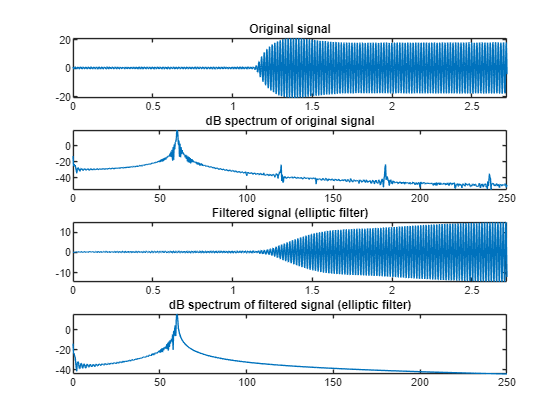

% Filtre con el filtro elíptico
y3=filter(df3, x);

% Visualización
figure;
% Dibujo de señal original
subplot(4,1,1)
plot(timeIndexes, x)
title('Original signal')
axis tight;
% Dibujo de espectro de señal original
subplot(4,1,2)
fftPlotdB(x,fs);
title('dB spectrum of original signal')
xlim([0 250])

% Dibujo de señal filtrada
subplot(4,1,3)
plot(timeIndexes, y3)
title('Filtered signal (elliptic filter)')
axis tight;
% Dibujo de espectro de señal filtrada
subplot(4,1,4)
fftPlotdB(y3,fs);
title('dB spectrum of filtered signal (elliptic filter)')
xlim([0 250])

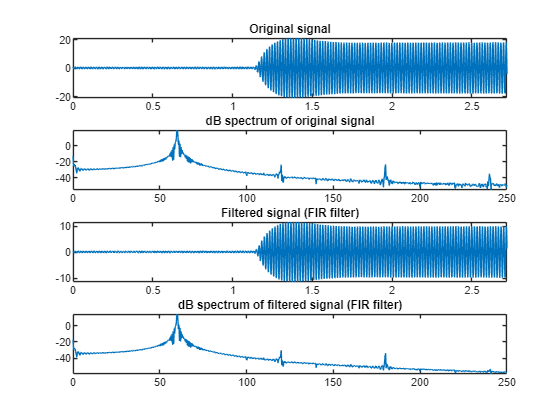



% Filtre ahora con el filtro FIR
y3=filter(df1, x);

% Visualización
figure;
% Dibujo de señal original
subplot(4,1,1)
plot(timeIndexes, x)
title('Original signal')
axis tight;
% Dibujo de espectro de señal original
subplot(4,1,2)
fftPlotdB(x,fs);
title('dB spectrum of original signal')
xlim([0 250])
% Dibujo de señal filtrada
subplot(4,1,3)
plot(timeIndexes, y3)
title('Filtered signal (FIR filter)')
axis tight;
% Dibujo de espectro de señal filtrada
subplot(4,1,4)
fftPlotdB(y3,fs);
title('dB spectrum of filtered signal (FIR filter)')
xlim([0 250])


% Comentario y discusion:
% + Describa el resultado de la aplicacion de cada filtro y discuta
%   si el resultado es el esperado para cada uno de ellos.

% COMENTARIO Y DISCUSION DE LOS RESULTADOS

%Aplicacion del filtro eliptico:

%Al aplicar el filtro eliptico, se observa que la señal filtrada conserva la componente frecuencial dominante, situada en
%en 60 Hz, mientras que las componentes de mayor frecuencia se atenuan considerablemente. Esto se aprecia en el espectro de amplitud en
%decibelios, donde los picos del segundo y tercer armónico presentes en 120, 180 y 240 Hz, dejan de ser claramente visibles despues del filtrado.

%En el dominio temporal, se observan diferencias entre la señal original y la señal filtrada. En primer lugar, la amplitud de la señal
%filtrada es menor que la de la señal original, pasando de valores aproximados de +/-20 a valores del orden de +/-12.
%Esto indica que el filtro atenúa la amplitud de la señal resultante. Ademas, el aumento de amplitud de las oscilaciones se produce
%algo mas tarde en la señal filtrada. Este comportamiento puede deberse al retardo provocado por la fase no lineal introducida a la
%señal original de este filtro tipo IIR.

%Aplicacion del filtro FIR:

%Al aplicar el filtro FIR, la señal filtrada tambien conserva la componente dominante situada en 60 Hz. Sin embargo, en el espectro de frecuencias
%todavia se aprecian picos secundarios en 120 y 180 Hz. Esto indica que esas componentes no se han eliminado completamente y que su atenuacion es menos evidente que
%en el resultado obtenido con el filtro eliptico.

%Al comparar la evolucion temporal de la señal original con la senal filtrada, se observa una reduccion considerable de la amplitud. Mientras que la señal original
%alcanza valores aproximados de +/-20, la señal filtrada presenta valores del orden de +/-10.Ademas las oscilaciones en este caso, comienzan con la misma
%amplitud que en el resto del recorrido de la señal. Esto es debido a que los filtros IRR no modifican la fase de la señal original y por tanto, no se va a
%ver modificada su forma en el dominio del tiempo.

% Comparacion y conclusion:

%Comparando ambos resultados, el filtro eliptico parece ofrecer una mayor atenuacion de las componentes frecuenciales no deseadas, al tiempo que
%conserva la componente dominante de la señal. El filtro FIR mantiene tambien la componente principal, pero presenta picos residuales mas
%visibles en las frecuencias superiores.

%En consecuencia, si el objetivo del filtrado es conservar la componente alrededor de 60 Hz y atenuar las componentes de mayor frecuencia, el
%resultado del filtro eliptico parece ajustarse mejor al comportamiento esperado.